close all
%
% Calculate Fundamental Matrix
%
addpath('../Helpers/');
addpath('../Helpers/CalibToolBox');
USE_NORMALIZED_ALGO = true;

% load first image and extract corners
img_left = imread('img_left.jpg');
fprintf('Select the eight points!\n');

Select the eight points!


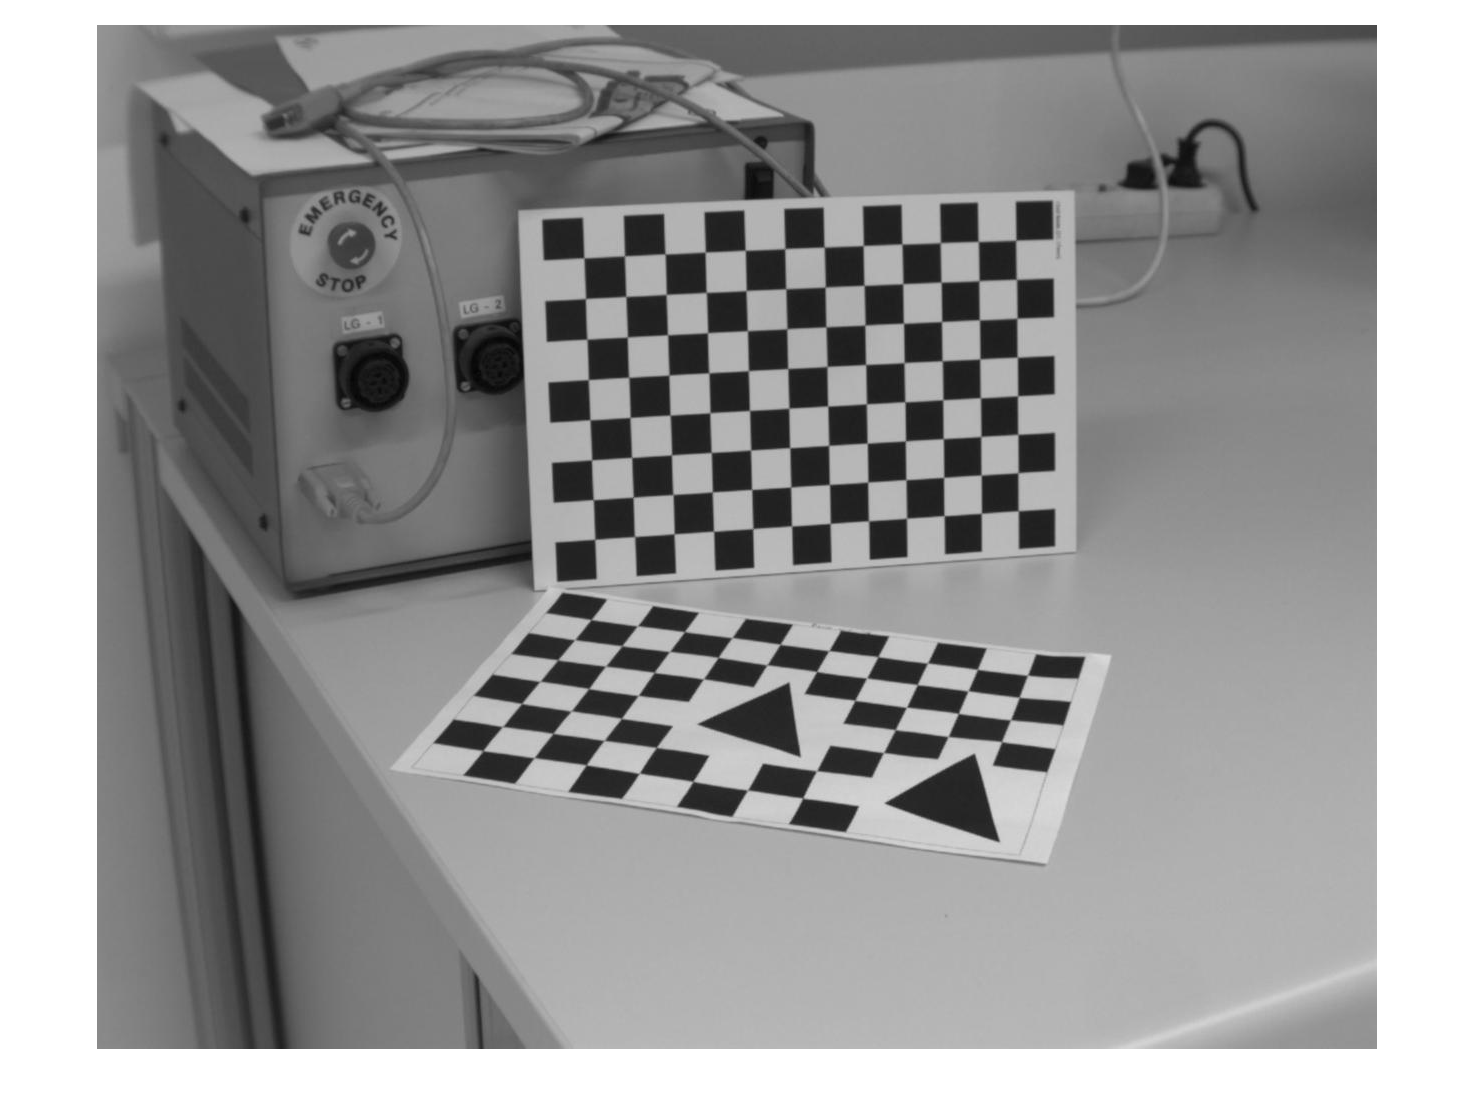

figure(1);
imshow(img_left);

%pts1=markCorners(img_left,8);
% 
img_right = imread('img_right.jpg');
fprintf('Select the eight points!\n');

Select the eight points!


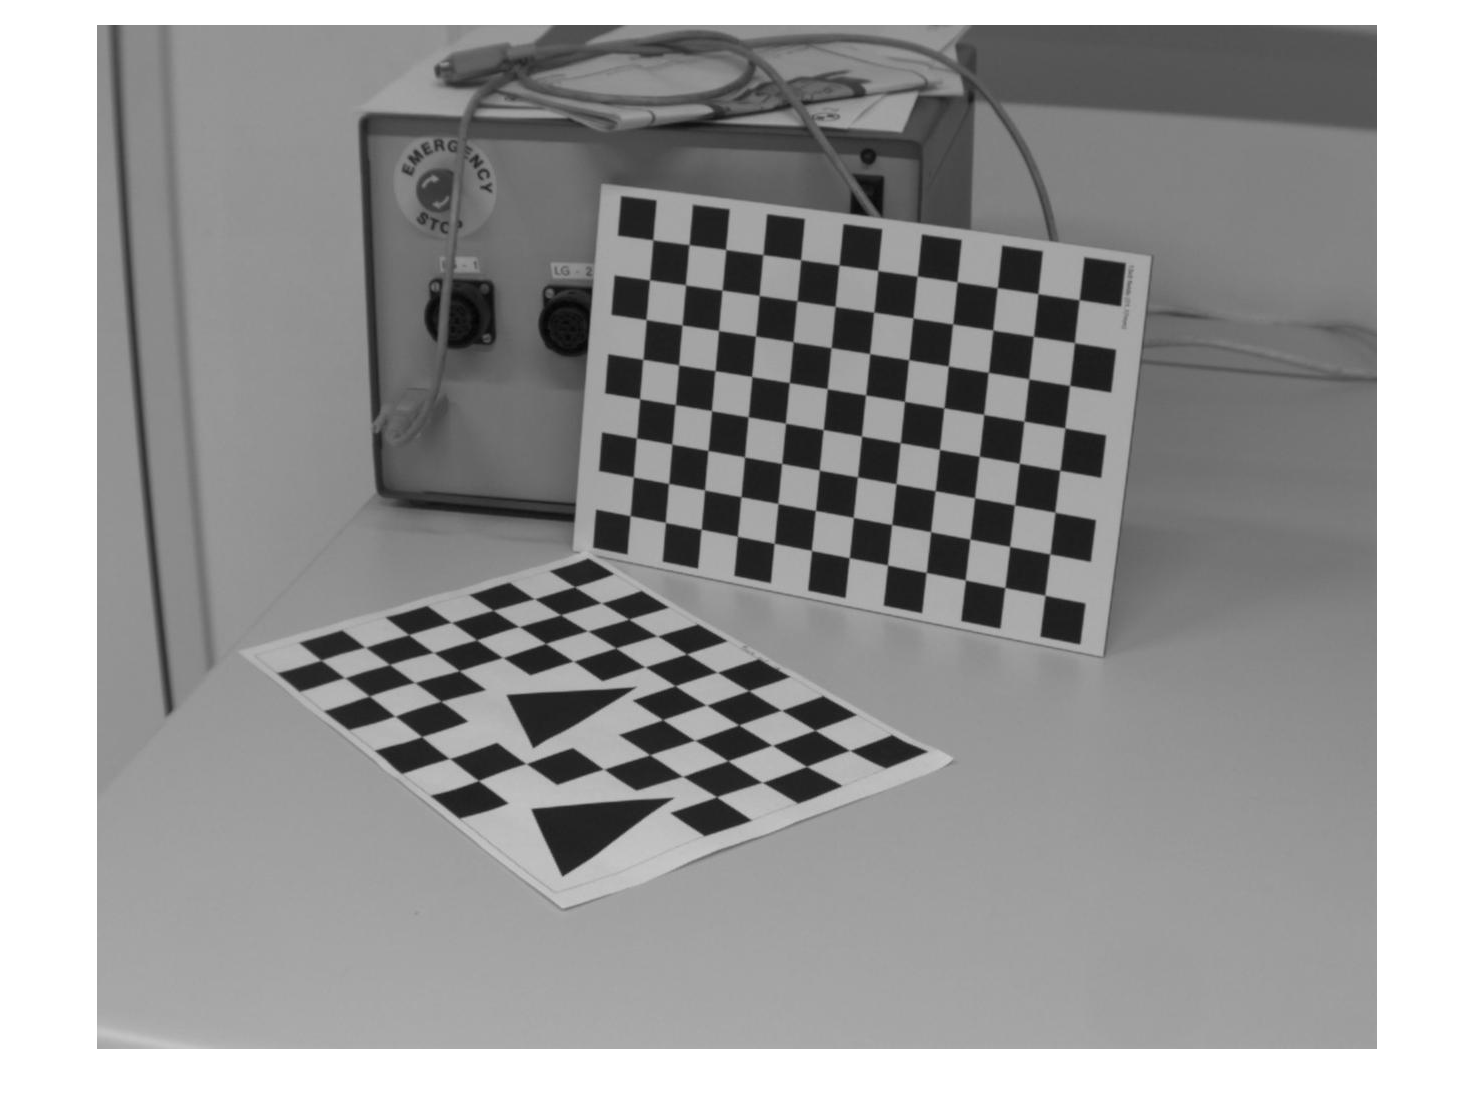

figure(2);
imshow(img_right);

%pts2=markCorners(img_right,8);

N = length(pts1);
% create arrays with homogenous coordinates:
pts1_hom = [pts1; ones(1, N)];
pts2_hom = [pts2; ones(1, N)];

% normalize the homogenous coordinates:
if USE_NORMALIZED_ALGO
    [pts1_hom, T1] = normalize_points(pts1_hom);
    [pts2_hom, T2] = normalize_points(pts2_hom);
end

## TODO: 1) setup linear equation system:

------------------------------------------------------------------------- $$ x_i'^T F x_i = 0 $$

=========================================================================

A = [pts2_hom(1,:) .* pts1_hom(1,:); pts2_hom(1,:) .* pts1_hom(2,:); pts2_hom(1,:) .* pts1_hom(3,:); ...
     pts2_hom(2,:) .* pts1_hom(1,:); pts2_hom(2,:) .* pts1_hom(2,:); pts2_hom(2,:) .* pts1_hom(3,:); ...
     pts2_hom(3,:) .* pts1_hom(1,:); pts2_hom(3,:) .* pts1_hom(2,:); pts2_hom(3,:) .* pts1_hom(3,:) ];

A = A';

[~,~,V] = svd(A);
F = reshape(V(:,end),3,3)';

## TODO: 2) impose rank 2 constraint:

------------------------------------------------------------------------- ... .. . =========================================================================

[U,S,V] = svd(F);
sig = sort(S(:),'descend');

Ss = diag([sig(1:2)' 0]);
Fs = U*Ss*V';


if USE_NORMALIZED_ALGO
    Fs = T2'*Fs*T1;
end

## TODO: 3) show stereo pair and plot the epipolar lines:

`        (complete and use the function 'drawEpipolarLine')`

`-------------------------------------------------------------------------`

`$$ l' = F x $$`

`$$ l^T x = 0 \leftarrow y = \frac{-l_3 - l_1 \cdot x}{l_2} $$`

`=========================================================================`

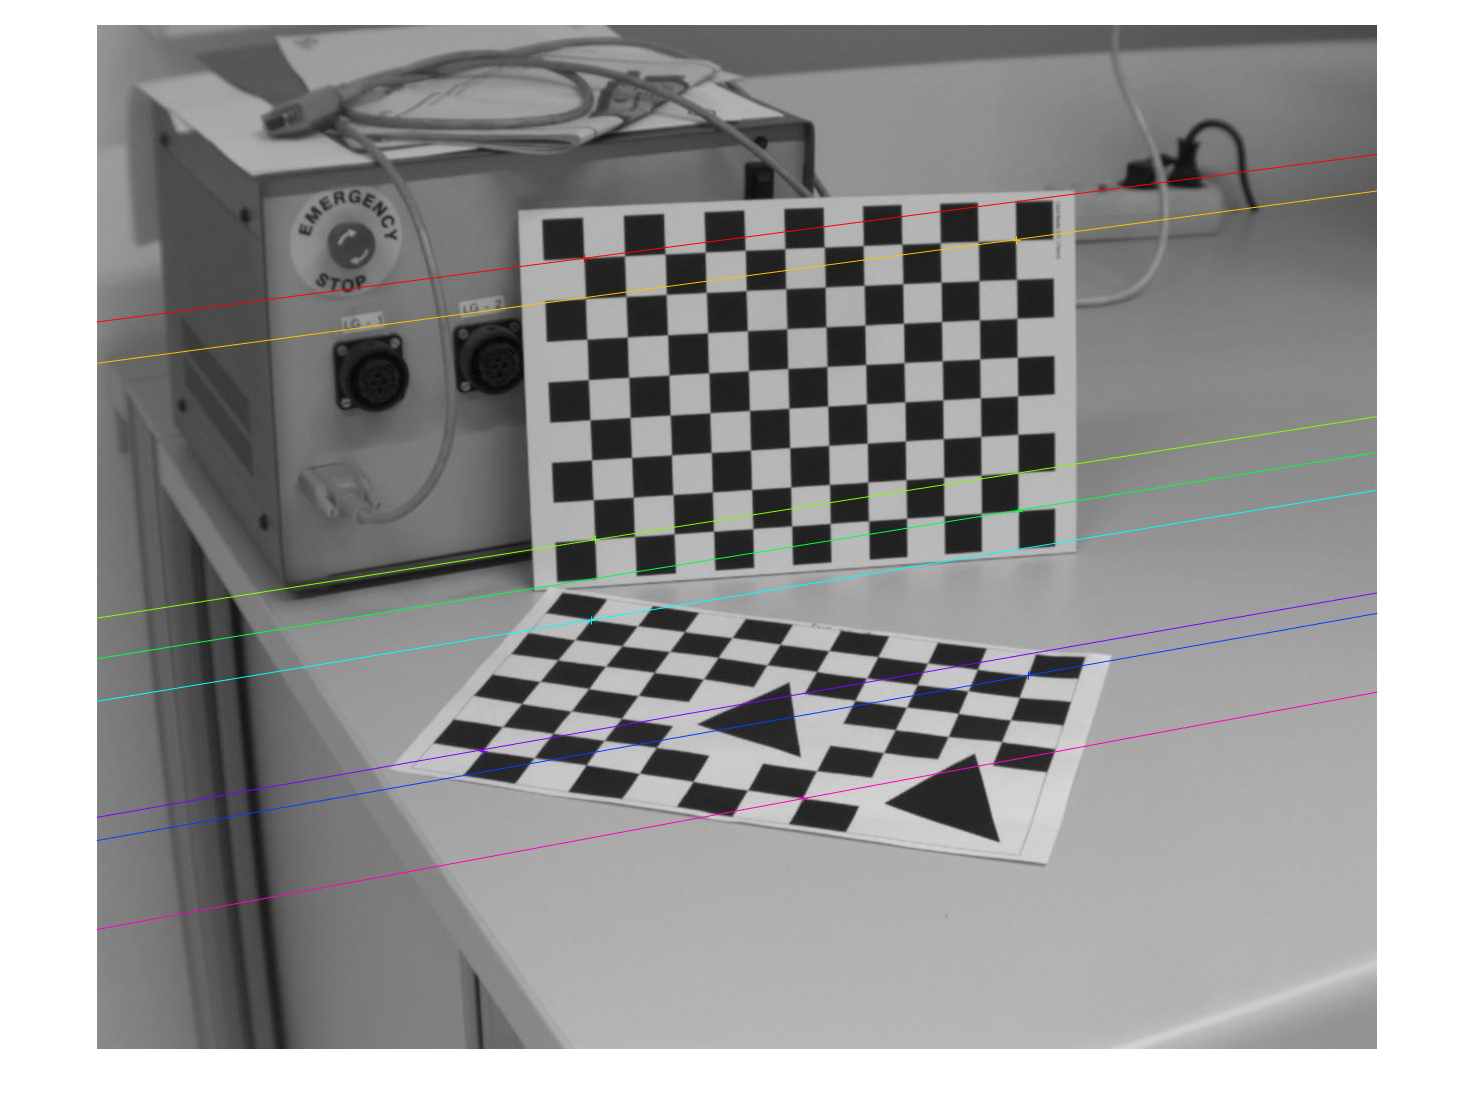

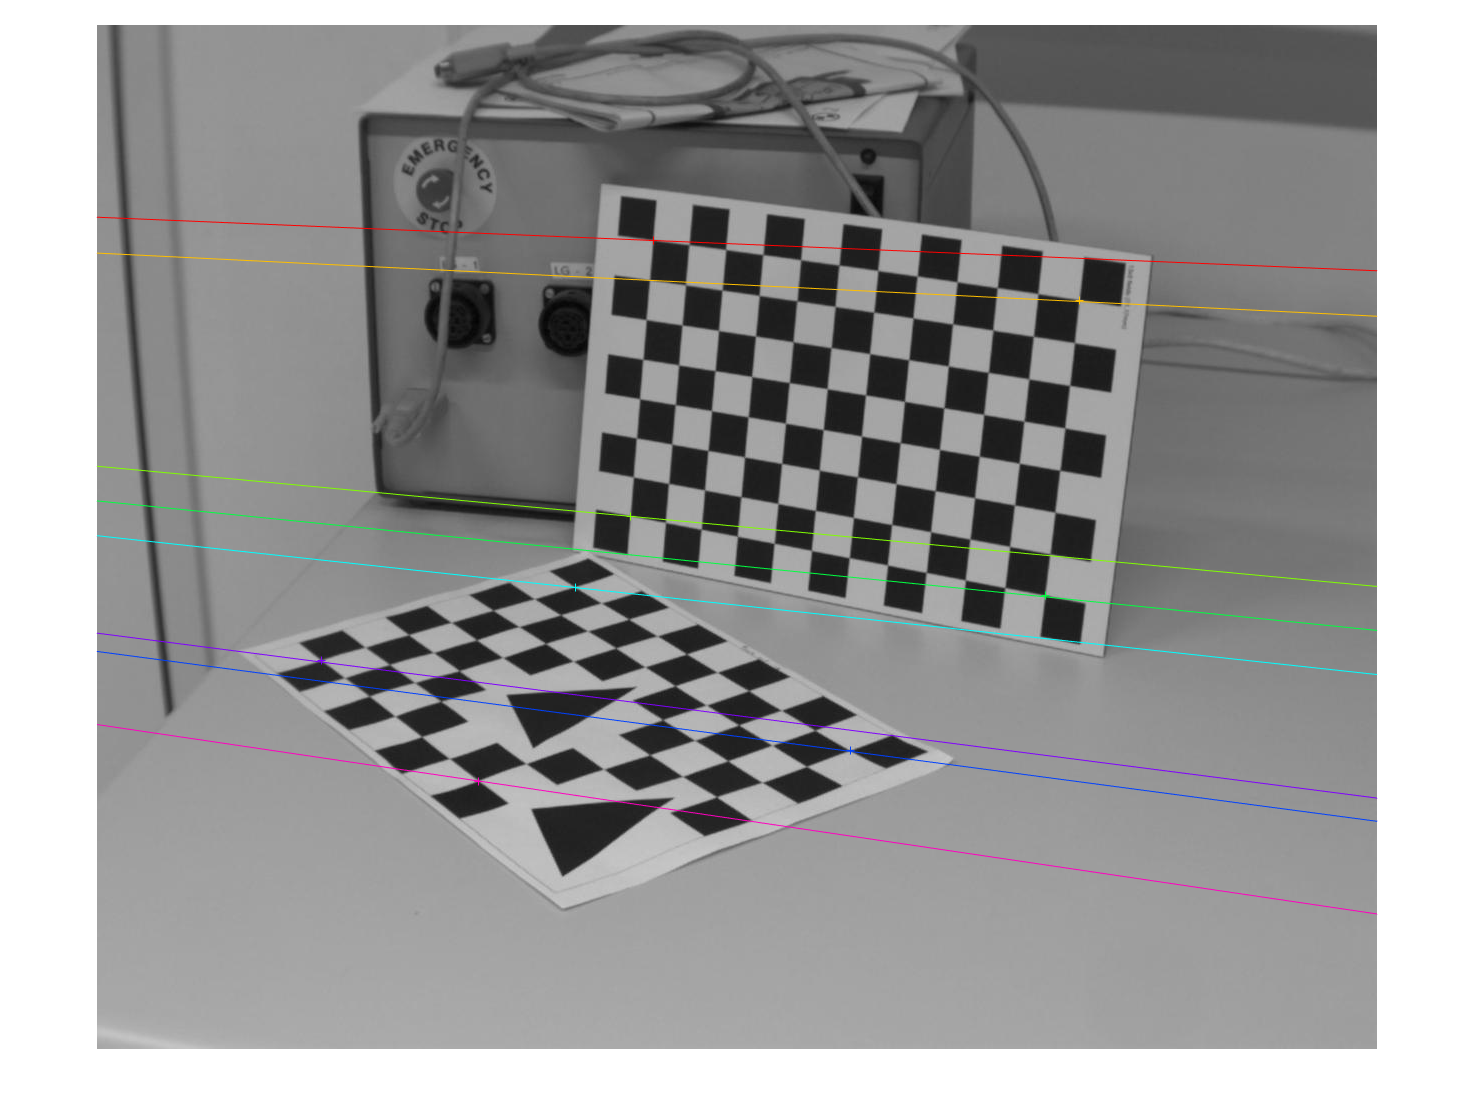

drawEpipolarLine(Fs, pts1, pts2);